# **EJERCICIOS ENTREGABLES** 

# Práctica 2: MATLAB Control System Toolbox: Funciones de transferencia, transformadas de Laplace y álgebra de bloques con MATLAB 

# Práctica 3: Polos y ceros de una función de transferencia, respuesta transitoria de un sistema de control con MATLAB y LTIViewer, precisión y error en estado estacionario

#### Ejercicio 1 (2 puntos). Funciones de transferencia en MATLAB. 

**Se tiene la función de transferencia **$G\left(s\right)=\frac{\alpha }{s^2 +s+\beta }$**. Se pide encontrar, utilizando comandos de control de flujo (for, while, etc.) y tf/zpk, los valores de α y β que conduzcan a un sistema sobreamortiguado (con dos polos con parte real pura y diferente) aproximable a uno de primer orden con ganancia estática unitaria. Razone la respuesta. **

Ya que la ganancia estática es unitaria, resulta:    $K_{\mathrm{estática}} =G\left(s=0\right)=\frac{\alpha }{\beta }=1\;\Rightarrow \;\alpha =\beta$

La segunda condición se centra en los polos, por lo que se estudian el polinomio del denominador de la función de transferencia:

$s=\frac{-b\pm \sqrt{b^2 -4\textrm{ac}}}{2a}$ , obligando a que $b^2 -4\mathrm{ac}>0$ para evitar que los polos del denominador contengan parte imaginaria y, por tanto, sean reales y diferentes (caso sobreamortiguado). En este sentido, se tiene que:$1-4\beta >0\;\;\;\Rightarrow \;\;\;\beta <\frac{1}{4}$

Es decir, el valor del parámetro β está restringido a un determinado rango, 0<β<0,25. A continuación, se debe estimar el valor o valores óptimas que permitan una aproximación a un sistema de primer orden (aproximación por polos dominantes).

Finalmente, se programa un bucle while, comenzando el barrido con el valor inicial β=0,01.

valores_beta=[];
beta=0.01;
while beta<0.25
    den=[1 1 beta];
    poles=roots(den);
    if isreal(poles) && poles(1)~=poles(2)
        if (poles(2)*10)>=poles(1)
           valores_beta=[valores_beta, beta];
        end
    end
    beta=beta+0.01;
end

En el bucle se barre el valor de β de 0,01 a 0,25 (valor límite), se calculan los polos y se establecen como solución, los valores sin parte imaginaria y donde se pueda aplicar una aproximación por polos dominantes.

Ahora, se devuelven los valores que se pueden tomar como solución:

valores_beta

valores_beta =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800


Por tanto, existen varias funciones de transferencia que se pueden establecer como solución. A continuación, se muestra el mapeo de polos correspondiente:

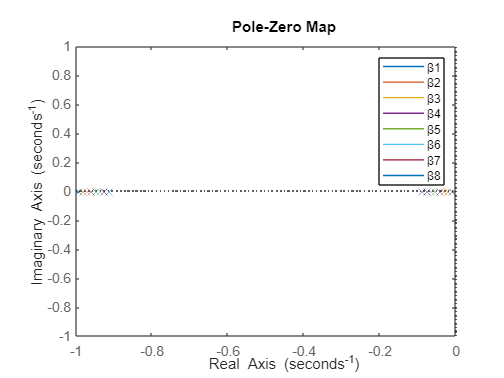

figure;
for i=1:length(valores_beta)
    beta=valores_beta(i);
    alfa=beta;
    G=tf([alfa],[1 1 beta]);
    polos=pole(G);
    pzmap(G); hold on
end
legend('β1','β2','β3','β4','β5','β6','β7','β8');

En efecto, se verifica que todos los sistemas propuestos son sobreamortiguados con posible aproximación por polos dominantes.

#### Ejercicio 2 (2,75 puntos). Diagramas de bloques. 

**Utilizando los comandos connect y sumblk de MATLAB (véase en Mathworks), construya el diagrama de bloques de la figura para, posteriormente, obtener las funciones de transferencia **$\frac{C\left(s\right)}{R\left(s\right)}$** y **$\frac{C\left(s\right)}{D\left(s\right)}$** , mediante el principio de superposición. Para ello, considere:  **$G_c \left(s\right)=\frac{5}{s+10}\;\;\;\;\;G_f \left(s\right)=25\;\;\;\;\;G_1 \left(s\right)=\frac{25}{s^2 +7s+30}\;\;\;\;\;G_p \left(s\right)=20\;\;\;\;\;H\left(s\right)=s+3$

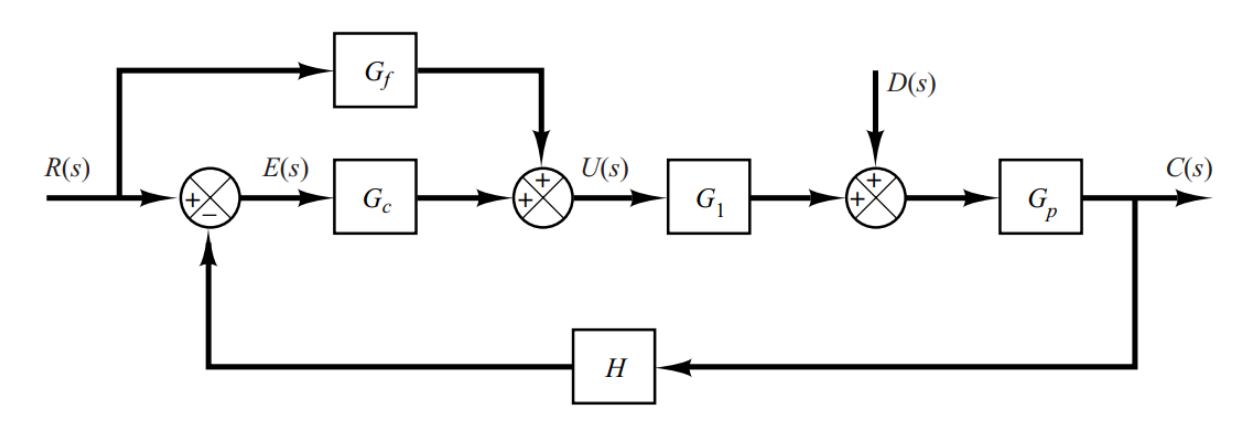

En primer lugar, se declaran las funciones de transferencia:

Gc=tf([5],[1 10]);
Gf=tf([25],[1]);
Gl=tf([25],[1 7 30]);
Gp=tf([20],[1]);
H=tf([1 3],[1]);

Después, se definen las entradas y salidas de cada bloque:

Gc.InputName='e';
Gc.OutputName='uc';
Gf.InputName='r';
Gf.OutputName='uf';
Gl.InputName='u';
Gl.OutputName='ul';
Gp.InputName='u2';
Gp.OutputName='c';
H.InputName='c';
H.OutputName='uh';

De igual forma, se determinan los puntos de suma:

S1=sumblk('e=r-uh');
S2=sumblk('u=uc+uf');
S3=sumblk('u2=d+ul');

A continuación, se genera el diagrama de bloques:

DB=connect(Gc,Gf,Gl,Gp,H,S1,S2,S3,{'r','d'},{'c'});

para, finalmente, calcular las funciones de transferencia:

tf(DB)

ans =
 
  From input "r" to output "c":
      1.25e04 s + 1.275e05
  ----------------------------
  s^3 + 17 s^2 + 2600 s + 7800
 
  From input "d" to output "c":
  20 s^3 + 340 s^2 + 2000 s + 6000
  --------------------------------
    s^3 + 17 s^2 + 2600 s + 7800
 
Continuous-time transfer function.
Model Proper

Se puede observar que el denominador de las dos funciones de transferencia coincide, independientemente de la entrada, lo que conduce a que los cálculos son correctos. En caso contrario, algún resultado sería erróneo pues si el sistema es el mismo, el denominador de la función de transferencia debe coincidir aunque se fijen diferentes entradas.

#### **Ejercicio 3 (2,5 puntos).**** Transformadas de Laplace y estudio de la respuesta transitoria de sistemas de control de primer y/o segundo orden. **

**La respuesta de un motor ante una entrada impulso unitario, r(t)=δ(t), se describe mediante la siguiente expresión: **$y\left(t\right)=\frac{3}{20}\;e^{-t} -\frac{3}{4}\;e^{-2\ldotp 9t}$**. Se pide: (i) Determinar la función de transferencia del motor, **$G\left(s\right)=\frac{Y\left(s\right)}{R\left(s\right)}$**, y su respuesta ante escalón unitario, registrando, en una variable, el valor de sobreoscilación y el tiempo de asentamiento. (ii) Si el motor se introduce en un esquema con realimentación unitaria negativa, represente la respuesta del sistema realimentado ante una entrada rampa, r(t)=4t.**

(i) A partir de la respuesta, se puede obtener la función de transferencia de la planta. En efecto, este es uno de los procediminetos más típicos para caracterizar sistemas. Además, al considerar una entrada en impulso unitario, se sabe teóricamente que la salida y la función de transferencia coinciden (R(s)=1). Aplicando la transformada de Laplace:

syms t
Y=laplace((3/20)*exp(-t)-(3/4)*exp(-2.9*t));
G=Y

$$G = \frac{3}{20\,\left(s+1\right)}-\frac{3}{4\,\left(s+\frac{29}{10}\right)}$$

Se tiene un sistema de segundo orden con dos polos negativos diferentes situados sobre el eje real; es decir, un sistema sobreamortiguado. A continuación, se representa la respuesta ante escalón unitario y se calculan los parámetros correspondientes:

R=1/s;
Y=G*R;
y=ilaplace(Y)

$$y = \frac{15\,{\mathrm{e}}^{-\frac{29\,t}{10}}}{58}-\frac{3\,{\mathrm{e}}^{-t}}{20}-\frac{63}{580}$$

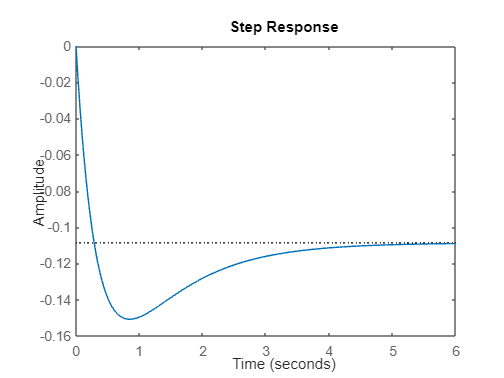

G=tf([-120 -63],[200 780 580]);
figure; step(G)

A=stepinfo(G);
overshoot=A.Overshoot

overshoot = 38.7782

settling_time=A.SettlingTime

settling_time = 4.2344

Se observa el sistema se estabiliza con un error finito negativo respecto a la entrada, exhibiendo una sobreoscilación pronunciada debido a la influencia del cero. Téngase en cuenta que ¡no es un sistema subamortiguado!

(ii) Ahora se introduce la planta en un control en lazo cerrado y se obtiene la respuesta del sistema ante una rampa de pendiente 4. Por tanto:

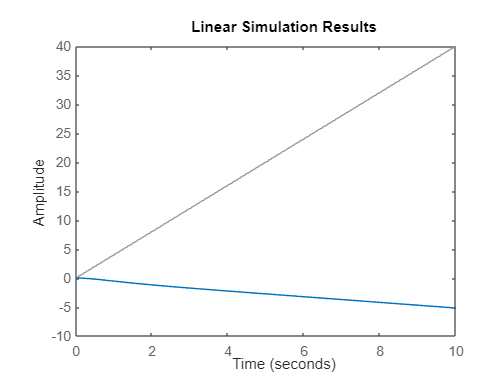

Glc=feedback(G,1);
t=linspace(0, 10, 100);
rampa=4*t;
lsim(Glc,rampa,t)

En este caso observamos que la salida oviamente no sigue a la entrada, con una tendencia, de nuevo, hacia valores negativos. Estos resultados eran predecibles a partir del resultado de (i). Se trata de un sistema tipo 0 con un error finito ante la entrada escalón y un error infinito ante la rampa.

#### Ejercicio 4 (2,75 puntos). Respuesta transitoria, precisión y error en estado estacionario para sistemas de orden superior. 

**Obtenga la respuesta, ante rampa unitaria, de un siguiente sistema de control en lazo cerrado, cuya función de transferencia es: **$G\left(s\right)=\frac{s+10}{s^3 +6s^2 +9s+10}$**. Realice un análisis analítico y gráfico. ¿Se puede despreciar algún polo (aproximación por polos dominantes) con el fin de reducir el orden del sistema? Con el análisis previo, analice los resultados desde un punto de vista del error y el tipo de sistema. Finalmente, exponga un mismo análisis, pero ahora considerando una entrada exponencial, **$r\left(t\right)=e^{-\;\frac{t}{2}}$** . ¿Qué tipo de respuesta transitoria y estacionaria resulta?**

Se define la función de transferencia y se representa la localización de sus polos y ceros:

G=tf([1 10],[1 6 9 10]);
[polos,ceros]=pzmap(G)

polos =   -4.4920 + 0.0000i
  -0.7540 + 1.2875i
  -0.7540 - 1.2875i


ceros = -10

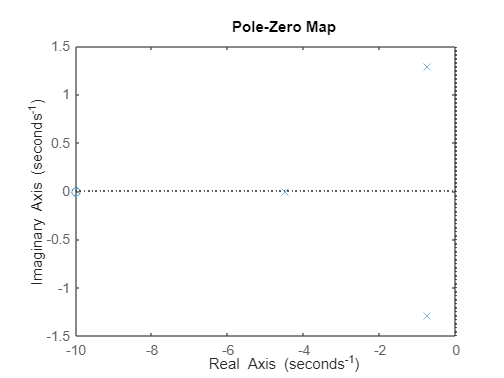

pzmap(G)

Se tiene un sistema de grado 3 con los tres polos correspondientes situados en el semiplano negativo, siendo dos ellos polos complejos conjugados.

Examinando los valores de las partes reales de los polos del sistema, se puede saber que no es posible reducirlo a uno de menor inferior porque la distancia entre ellos no es lo suficientemente grande. El polo que está más alejado del eje imaginario no está a una distancia de al menos x10 respecto a los polos complejos.

Ahora, se estudia la respuesta ante una entrada en rampa unitaria analítica

syms s
G=(s+10)/(s^3+6*s^2+9*s+10);
X=1/(s^2);
Y=G*X;
y=ilaplace(Y)

$$y = \begin{array}{l} t+\frac{4\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{2}}{\sigma_{1}}\right)}{5}+\frac{6\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{2}}}{\sigma_{1}}\right)}{5}+\frac{19\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{2}\,t}\,\sigma_{2}}{3\,\left(4\,\sigma_{2}+{\sigma_{2}}^{2}+3\right)}\right)}{5}-\frac{4}{5}\\ \mathrm{where}\\ \sigma_{1}=3\,\left({\sigma_{2}}^{2}+4\,\sigma_{2}+3\right)\\ \sigma_{2}=\mathrm{root}\left(z^{3}+6\,z^{2}+9\,z+10,z,k\right) \end{array}$$

y gráficamente:

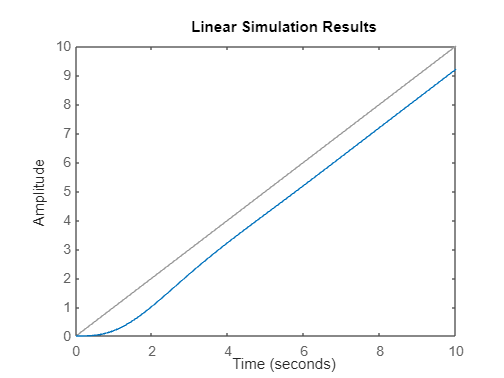

G=tf([1 10],[1 6 9 10]);
t=linspace(0,10,100);
rampa=t;
lsim(G,rampa,t)

Al tener la función de transferencia en lazo cerrado, se puede calcular directamente el error verdadero en estado estacionario:

[y,t]=lsim(G,rampa,t);
ess_vel_absoluto = rampa(end)-y(end)

ess_vel_absoluto = 0.7996

ess_vel_relativo = (rampa(end)-y(end))*100/rampa(end)

ess_vel_relativo = 7.9965

lo que conduce a la conclusión de que se tiene un sistema tipo 1 (error finito en este escenario).

Ahora se estudia el comportamiento del sistema ante una entrada de naturaleza exponencial; primero de forma analítica

syms s t
G=(s+10)/(s^3+6*s^2+9*s+10);
x=exp(-t/2);
X=laplace(x);
Y=G*X;
y=ilaplace(Y)

$$y = \begin{array}{l} \frac{76\,{\mathrm{e}}^{-\frac{t}{2}}}{55}-\frac{76\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{2}}{\sigma_{1}}\right)}{55}-\frac{84\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{2}}}{\sigma_{1}}\right)}{11}-\frac{38\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{2}\,t}\,\sigma_{2}}{3\,\left(4\,\sigma_{2}+{\sigma_{2}}^{2}+3\right)}\right)}{5}\\ \mathrm{where}\\ \sigma_{1}=3\,\left({\sigma_{2}}^{2}+4\,\sigma_{2}+3\right)\\ \sigma_{2}=\mathrm{root}\left(z^{3}+6\,z^{2}+9\,z+10,z,k\right) \end{array}$$

y después gráficamente:

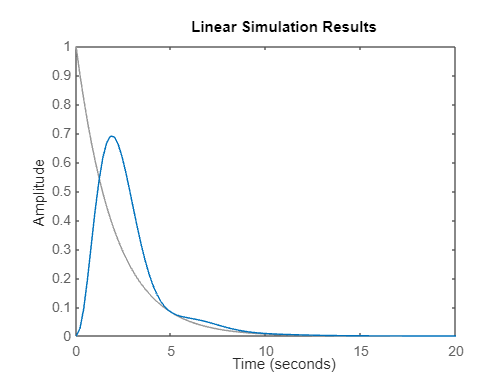

G=tf([1 10],[1 6 9 10]);
t=linspace(0,20,100);
exponencial=exp(-t/2);
lsim(G,exponencial,t)

Como la entrada tiende a 0, es lógico que la salida también se extinga con el paso del tiempo, pues el sistema es estable. Un estudio de errores más allá no tendría sentido, pues la entrada de naturaleza exponencial no está catalogada como para cuantificar el comportamiento de errores del sistema.